# Read Navigation Data from Galileo Almanac File

Read navigation data from a Galileo almanac file and use the navigation data to:

- Get satellite positions, velocities, and IDs at a given timestamp.

- Compute satellite visibility and look angles for a given receiver position by using the extracted satellite positions.

First, read GPS navigation message data from a Galileo almanac file.

filename = "D:\Categorized\polito\S3\Interdisciplinary Projects\Implementations\_feasibility\2024-10-15.xml";
data = galalmanacread(filename)

data = 25×16 timetable
            Time            SVID    aSqRoot        ecc          deltai       omega0      omegaDot          w           m0           af0            af1        iod       t0a       wna     statusE5a    statusE5b    statusE1B
    ____________________    ____    ________    __________    __________    ________    ___________    _________    ________    ___________    ___________    ___    _________    ____    _________    ____

Specify the timestamp for which to find the satellite positions, velocities, and IDs.

t = datetime(2024, 10, 15, 6, 46, 42)

t = datetime
   15-Oct-2024 06:46:42


Get the satellite positions, velocities, and IDs at the specified timestamp by using the `gnssconstellation` function.

[satPos,satVel,satID] = gnssconstellation(t,data,GNSSFileType="galalmanac");

Specify a receiver position in geodetic coordinates (latitude, longitude, altitude) to compute the satellite look angles and visibility.

recPos = [45.3013162 7.6782972 0];

Specify the elevation mask angle for the receiver.

maskAngle = 5;

Compute the look angles and visibilities of satellite positions for the given receiver position. The `vis` output indicates which satellites are visible. Get the total using `nnz`.

[az,el,vis] = lookangles(recPos,satPos,maskAngle);
az

az =   111.8051
   50.8494
  321.4965
   36.1339
    8.2707
  202.4333
  134.3990
   22.2558
  302.2514
  149.6292


el

el =   -26.0563
   35.9653
  -77.5432
   -9.0391
  -65.0056
   30.0743
   71.6602
  -49.0519
  -73.1167
  -86.4930


fprintf('%d satellites visible at %s.\n',nnz(vis),t)

6 satellites visible at 15-Oct-2024 06:46:42.


Plot the visible satellite positions with the elevation mask.

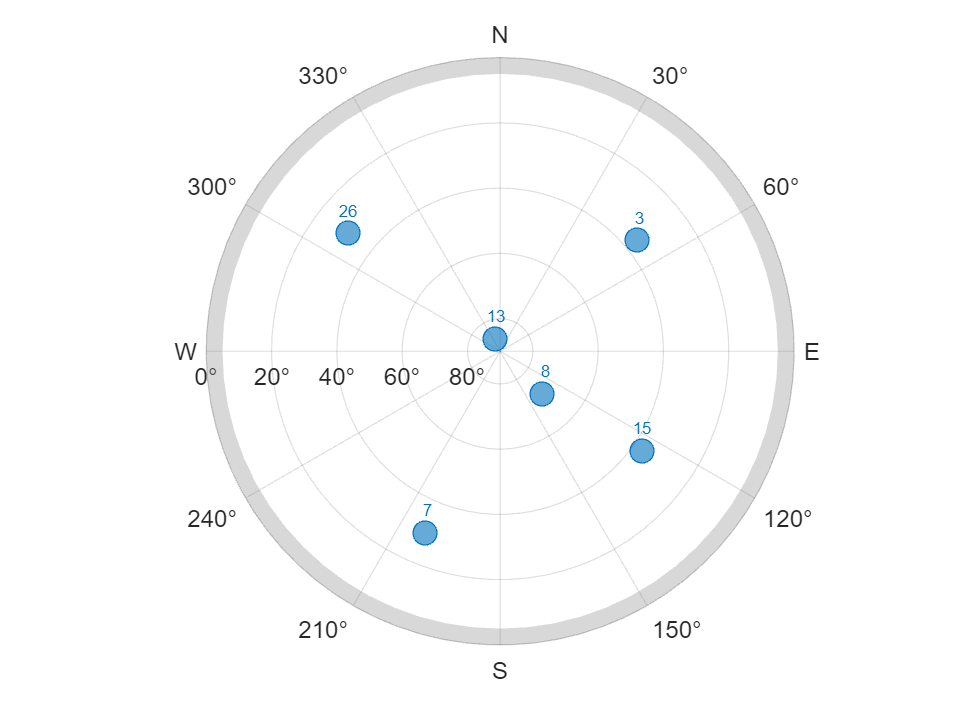

figure
skyplot(az(vis),el(vis),satID(vis),MaskElevation=maskAngle)

*Copyright 2023 The MathWorks, Inc.*

satPos

satPos = 1.0e+07 *

   -0.1356    2.6602   -1.2895
    0.3578    1.6574    2.4250
   -2.3522   -0.8021   -1.6081
   -1.7977    1.5169    1.7964
   -2.8496   -0.1679   -0.7835
    2.9211   -0.4683   -0.0830
    2.2923    0.8416    1.6715
   -2.9236    0.4608    0.0748
   -2.2045   -1.1807   -1.5849
   -1.9375   -0.1490   -2.2334


satVel

satVel = 1.0e+03 *

   -0.4399    1.2180    2.5605
   -2.4110    0.3364    0.1265
    1.6031   -0.1792   -2.2557
   -1.7792    0.2906   -2.0253
    0.7813   -0.0699   -2.8345
    0.0737   -0.0705    3.0091
   -1.6698    0.1773    2.2001
   -0.0641    0.0882   -3.0204
   -1.0849   -1.1736    2.3821
   -1.4293   -1.7304    1.3559
